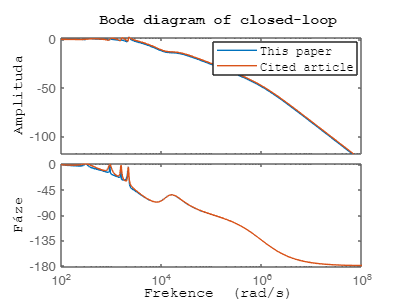

% L_i = 1.2e-3;        % H
% L_g = 0.7e-3;        % H
% C_f = 9e-6;          % F
% R_d = 8;             % Ohms
% 
% T_S = 1e-6;          % s
% 
% s = tf('s');
% T_D = (1/(1+T_S*s));
% G_F = ((1/(L_i*s))*(((s^2)+(s*R_d/L_g)+(1/(L_g*C_f)))/((s^2)+(s*((L_i*R_d+L_g*R_d)/(L_i*L_g)))+((L_i+L_g)/(L_i*L_g*C_f)))))*T_D;
% 
% 
% omega_0 = 2*pi*50;   % rad/sec
% omega_c = 0.5;       % rad/sec
% omega_c3 = 2.5;    % rad/sec
% omega_c5 = 4.5;    % rad/sec
% omega_c7 = 10;     % rad/sec
% 
% C_pid = pidtune(G_F, 'pid')
% 
% G_cl_pid = feedback(G_F*C_pid,1);
% 
% C = @(K) K(1) + ...
%          K(2)*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2))) + ...
%          K(3)*((2*omega_c3*s)/((s^2) + (2*omega_c3*s) + ((3*omega_0)^2))) + ...
%          K(4)*((2*omega_c5*s)/((s^2) + (2*omega_c5*s) + ((5*omega_0)^2))) + ...
%          K(5)*((2*omega_c7*s)/((s^2) + (2*omega_c7*s) + ((7*omega_0)^2)));
% 
% K_fp = [6.8  1498.72  211.208  83.867  40.834]
% K = [6.0669  418.8029   25.3298   12.6577   45.8612]
% 
% % Closing the loop:
% G_cl_fp = feedback(G_F*C(K_fp),1);
% G_cl = feedback(G_F*C(K),1);
% 
% h = subplot(2,2,1);
% % Plotting the step response of the closed-loop system:
% step(G_cl,G_cl_fp);
% title('Skoková odezva uzavřené smyčky','FontName', 'Courier')
% xlabel('Čas','FontName', 'Courier')
% ylabel('Amplituda','FontName', 'Courier')
% 
% subplot(2,2,4);
% bode(G_cl,G_cl_fp);
% title('Bodeho charakteristika uzavřené smyčky','FontName', 'Courier')
% xlabel('Frekence','FontName', 'Courier');
% axes=findobj('type','axes');
% h_magnitude=get(axes(2),'YLabel');
% h_phase=get(axes(1),'YLabel');
% set(h_phase,'String','Fáze','FontName','Courier');
% set(h_magnitude,'String','Amplituda','FontName', 'Courier');
% 
% subplot(2,2,3);
% bode(C(K),C(K_fp));
% title('Bodeho charakteristika PR regulátoru','FontName', 'Courier')
% xlabel('Frekence','FontName', 'Courier');
% axes=findobj('type','axes');
% h_magnitude=get(axes(2),'YLabel');
% h_phase=get(axes(1),'YLabel');
% set(h_phase,'String','Fáze','FontName','Courier');
% set(h_magnitude,'String','Amplituda','FontName', 'Courier');
% 
% 
% subplot(2,2,2);
% nyquist(G_cl,G_cl_fp);
% axis equal
% title('Nyquistova charakteristika uzavřené smyčky','FontName', 'Courier')
% xlabel('Re','FontName', 'Courier')
% ylabel('Im','FontName', 'Courier')
% 
% 
% 
% leg = legend("Tento článek","Původní článek",'FontName', 'Courier',Location='northoutside');
% % lh=legend(h,'location','east')
% set(leg,'position',[0.47125,0.4685,0.1725,0.069])
% 
% set(gcf, 'Position', [0, 0, 900, 500])
% print(gcf, '-dpng', 'porovnani_s_PR.jpg')
% 
% % Nastavení parametrů signálu
% fs = 50000*2*pi; % vzorkovací frekvence
% f0 = 50*2*pi; % hlavní frekvence signálu
% t = 0:(1/fs):(1/f0); % časový vektor
% U = 385; % amplituda signálu
% H = 30; % max harmonicka
% 
% % x = U*square(2*pi*t*f0,50); % Obdélníkový signál
% 
% % Vytvoření základního sinusového signálu
% x = U*sin(2*pi*f0*t);
% 
% h = 3:2:H;
% for n = h
%     x = x + (U*(1/n))*sin(2*pi*n*f0*t);
% end
% 
% pxx_norm_vstup = 100*(periodogram(x,[],length(x),fs))/(max(periodogram(x,[],length(x),fs))); % normalizace hodnot na procenta
% 
% y = lsim(G_cl,x,t);
% pxx_norm_vystup = 100*(periodogram(y,[],length(x),fs))/(max(periodogram(y,[],length(x),fs))); % normalizace hodnot na procenta
% 
% y_fp = lsim(G_cl_fp,x,t);
% pxx_norm_vystup_fp = 100*(periodogram(y_fp,[],length(x),fs))/(max(periodogram(y_fp,[],length(x),fs))); % normalizace hodnot na procenta
% 
% y_pid = lsim(G_cl_pid,x,t);
% pxx_norm_vystup_pid = 100*(periodogram(y_pid,[],length(x),fs))/(max(periodogram(y_fp,[],length(x),fs))); % normalizace hodnot na procenta
% 
% 
% thd = 0;
% for n = 4:2:(2*length(h))+2
%     fprintf("THD " + num2str(n-1) + ". harmonické je: %0.2f%%\n",pxx_norm_vstup(n));
%     thd = thd + pxx_norm_vstup(n);
% end
% 
% fprintf('THD je: %0.2f%%\n',thd);
% 
% 
% 
% plot(t,y);
% hold on
% plot(t,y_fp);
% plot(t,y_pid);
% plot(t,x);
% title('Sinusový signál s harmonickými složkami');
% xlabel('Cas (s)');
% ylabel('Amplituda (U)');
% legend("Výstup","From paper", "PID","Vstup")
% 
% thd = 0;
% for n = 4:2:(2*length(h))+2
%     fprintf("THD " + num2str(n) + ". harmonické je: %0.2f%%\n",pxx_norm_vystup(n));
%     thd = thd + pxx_norm_vystup(n);
% end
% fprintf('THD je: %0.2f%%\n',thd);
% 
% thd = 0;
% for n = 4:2:(2*length(h))+2
%     fprintf("THD " + num2str(n) + ". harmonické je: %0.2f%%\n",pxx_norm_vystup_fp(n));
%     thd = thd + pxx_norm_vystup_fp(n);
% end
% fprintf('THD je: %0.2f%%\n',thd);
% 
% thd = 0;
% for n = 4:2:(2*length(h))+2
%     fprintf("THD " + num2str(n) + ". harmonické je: %0.2f%%\n",pxx_norm_vystup_pid(n));
%     thd = thd + pxx_norm_vystup_pid(n);
% end
% fprintf('THD je: %0.2f%%\n',thd);
% 
% 
% 
% 
% h = subplot(3,1,3);
% nyquist(G_cl,G_cl_fp);
% axis equal
% title('Nyquistova charakteristika uzavřené smyčky','FontName', 'Courier')
% xlabel('Re','FontName', 'Courier')
% ylabel('Im','FontName', 'Courier')
% 
% subplot(3,1,2);
% bode(G_cl,G_cl_fp);
% title('Bodeho charakteristika uzavřené smyčky','FontName', 'Courier')
% xlabel('Frekence','FontName', 'Courier');
% axes=findobj('type','axes');
% h_magnitude=get(axes(2),'YLabel');
% h_phase=get(axes(1),'YLabel');
% set(h_phase,'String','Fáze','FontName','Courier');
% set(h_magnitude,'String','Amplituda','FontName', 'Courier');



bode(G_cl,G_cl_fp);
title('Bode diagram of closed-loop','FontName', 'Courier')
xlabel('Frekence','FontName', 'Courier');
axes=findobj('type','axes');
h_magnitude=get(axes(2),'YLabel');
h_phase=get(axes(1),'YLabel');
set(h_phase,'String','Fáze','FontName','Courier');
set(h_magnitude,'String','Amplituda','FontName', 'Courier');

% leg = legend("Navrhovaný PR regulátor","PR regulátor z článku [2]",'FontName', 'Courier',Location='southeast');
leg = legend("This paper","Cited article",'FontName', 'Courier',Location='southwest');
% lh=legend(h,'location','east')
legend("Position",[0.53167,0.74998,0.3625,0.115])

set(gcf, 'Position', [0, 0, 400, 300])
print(gcf, '-dpng', 'porovnani_s_PR4_en.jpg')


stepinfo(G_cl).Overshoot

ans = 0.2614

stepinfo(G_cl).RiseTime

ans = 5.9489e-04

stepinfo(G_cl).TransientTime

ans = 8.7693e-04


stepinfo(G_cl_fp).Overshoot

ans = 6.1100

stepinfo(G_cl_fp).RiseTime

ans = 4.6623e-04

stepinfo(G_cl_fp).TransientTime

ans = 0.0208